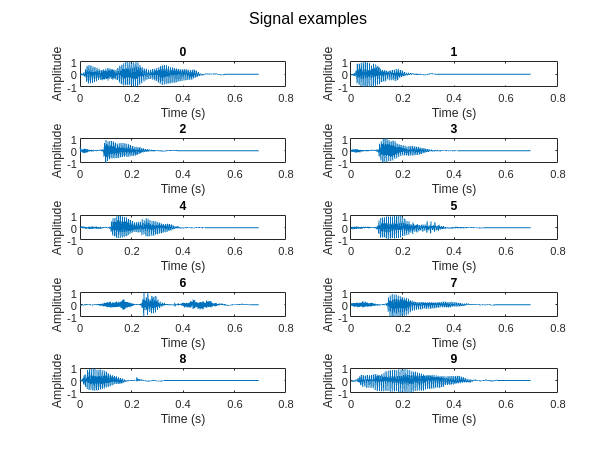

% audioFeatures[x, y, z] is the feature z, of the (x-1)th sample of digit y-1
% Features: 
% 1 - Total energy
% 2 - Standard deviation
% 3 - Max amplitude
% 4 - Zero crossing rate
% 5 - Duration
audioFeatures = zeros(50, 10, 5);

% Start by plotting the first sample of each digit (id = 0)
figure;
audioFeatures(1, :, :) = getFeatures(0, 1);
sgtitle('Signal examples');

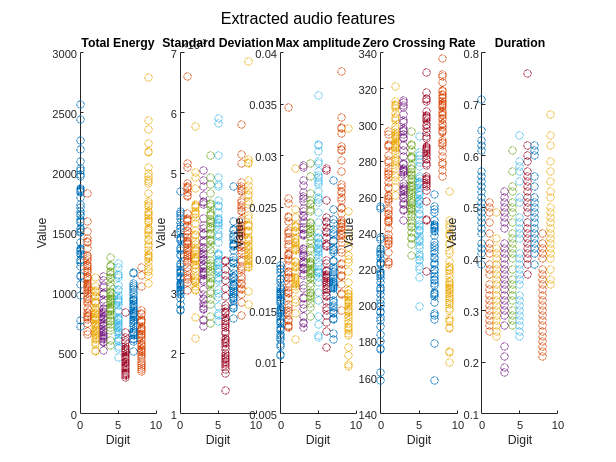

% i + 1 because MATLAB uses 1-based indexing but the audio file names use 0-based indexing
for i = 1:49
    audioFeatures(i+1, :, :) = getFeatures(i, 0);
end
audioFeatures;
% Scatter plot the 5 chosen audio features
figure;
featureStrings = {'Total Energy', 'Standard Deviation', 'Max amplitude', 'Zero Crossing Rate', 'Duration'};
for feature = 1:5
    subplot(1, 5, feature);
    % Iterate through every digit
    for digit = 1:10
        scatter(repmat(digit-1, 1, 50), audioFeatures(:, digit, feature));
        hold on;
    end
    title(featureStrings{feature});
    xlabel('Digit');
    ylabel('Value');
    hold off;
end
sgtitle('Extracted audio features');

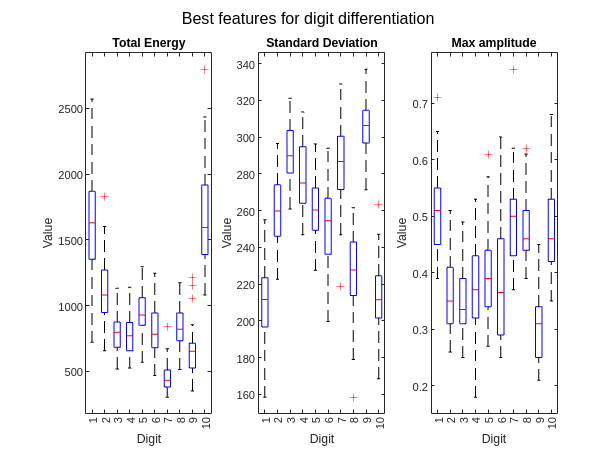

figure;
bestFeatures = [1, 4, 5];
for i = 1:length(bestFeatures)
    feature = bestFeatures(i);
    subplot(1, length(bestFeatures), i);
    % Prepare data for boxplot
    data = [];
    group = [];
    for digit = 1:10
        data = [data; audioFeatures(:, digit, feature)];
        group = [group; repmat(digit, 50, 1)];
    end
    boxplot(data, group);
    title(featureStrings{i});
    xlabel('Digit');
    ylabel('Value');
end
sgtitle('Best features for digit differentiation');